# Domaci zadatak iz predmeta upravljanje elektromotornim pogonima

Radila: Dragana Ninkovic 2019/0052

Napomena: Svi proracuni i diskretizacije su izracunati i na papiru i u matlabu pa su u nekim funkcijama korisceni razultati s papira a u nekim iz matlaba. U izvestaju se vide svi konacni rezultati formula sa papira i proracuni u matlabu koji ih potvrdjuju.

## 1) Program za podesavanje vrednosti

% Inicijalizacija parametara
% Nominalnli podaci
clear
close all;
clc;

Un = 230; % V
In = 26; % A
nn = 1430; % rpm
wn = nn*pi/30; % rad/s

% Motor
Ra = 0.9; % Ohms
La = 0.025; % H
Ta = La/Ra; % vremenska konstanta indukta
PsiFn = (Un-Ra*In)/wn; % Nominalni fluks
mn = PsiFn*In; % Nominalni momenat
J = 0.5; % kg*m^2 

% Aktuator
Udc = 250; % napod DC linka
fc = 1000; % uÄ?estanost komutacije Ä?opera
Tc = 1/fc;
ucmax=1;
ucmin=-1;

Ts=10e-6; % perioda odabiranja
%% Podesavanja

% vremenske konstante u sekundama
Tpi = 2.6e-3;
Tpu = 2.6e-3;
Tpw = 5e-3;

% pojacanja 
Kpi = 0.2;% V/A
Kpw = 10/150;% V*s/rad

## 2) Proracuni

- *regulacija struje*

Prvo sa radi regulacija strujne petlje. Vremenska konstanta Tpi moze da predje iz povratne sprege u deo sa coperom. Izvrsicemo kompenzaciju najsporijeg pola $Ti = Ta$ i koristiti simetricni modalni optimum $a_k^2=2*a_{k-1}*a_{k+1}$. Pri izvodjenju funkcije prenosa EMS mozemo smatrati da je konstantno jer se mehanicke velicine mnogo sporije menjaju od elektricnih, pa ono ne ulazi u funkciju prenosa jer je poremecaj.

syms s Ki
Kc = Udc;
Ti = Ta;
Te = Tc+Tpi;
F_PI_I = Ki *(1+s*Ti)/(s*Ti);
F_chopper = Kc/(1+s*Te);
F_motor = (1/Ra)/(1+s*Ta);
W_I = F_PI_I*F_chopper*F_motor;
F_I = ( W_I)/...
    (1+W_I*Kpi);
disp('F_I')

F_I


disp(simplify(F_I))

$$\frac{25000000\,\mathrm{Ki}}{9\,s^{2}+2500\,s+5000000\,\mathrm{Ki}}$$

a0 = 5000000*Ki;
a1 = 2500;
a2 = 9;
Ki=double(solve(a1*a1==(2*a2*a0),Ki));

*Dobijena funkcija prenosa je *$\frac{\frac{1}{Kpi}}{2Te^2s^2+2Tes+1}\approx\frac{\frac{1}{Kpi}}{2Tes+1}$ 

F_I = 1/Kpi/(2*Te*s+1);

- *regulacija brzine*

Vremenska konstanta Tpw moze iz povratne sprege da predje u deo sa funkcijom prenosa strujne petlje i ponovo koristimo simterican optimum za namestanje parametara

syms Kw Tw
Te_prim = 2*Te+Tpw;
F_PI_W = Kw*(1+s*Tw)/(s*Tw);
F_I = 1/Kpi/(1+s*Te_prim);
W_W = F_PI_W*F_I*PsiFn/(J*s);
F_W = W_W/(1+W_W*Kpw);
disp('F_W:')

F_W:


disp(simplify(F_W))

$$\frac{19416701672258540625\,\mathrm{Kw}\,\left(\mathrm{Tw}\,s+1\right)}{17169973579350016\,\mathrm{Tw}\,s^{3}+1407374883553280000\,\mathrm{Tw}\,s^{2}+1294446778150569375\,\mathrm{Kw}\,\mathrm{Tw}\,s+1294446778150569375\,\mathrm{Kw}}$$

a3 = 17169973579350016*Tw;
a2 = 1407374883553280000*Tw;
a1 = 1294446778150569375*Kw*Tw;
a0 = 1294446778150569375*Kw;
[Tw,Kw] =solve([(a1*a1)==(2*a0*a2),(a2*a2)==(2*a1*a3)],[Tw,Kw]);
Kw = double(Kw(1));
Tw = double(Tw(1));
table(Ti, Ki, Tw, Kw)

ans = 1×4 table
       Ti          Ki         Tw        Kw  
    ________    ________    ______    ______

    0.027778    0.069444    0.0488    44.559


## 3) Simulink i funkcije u Simulinku

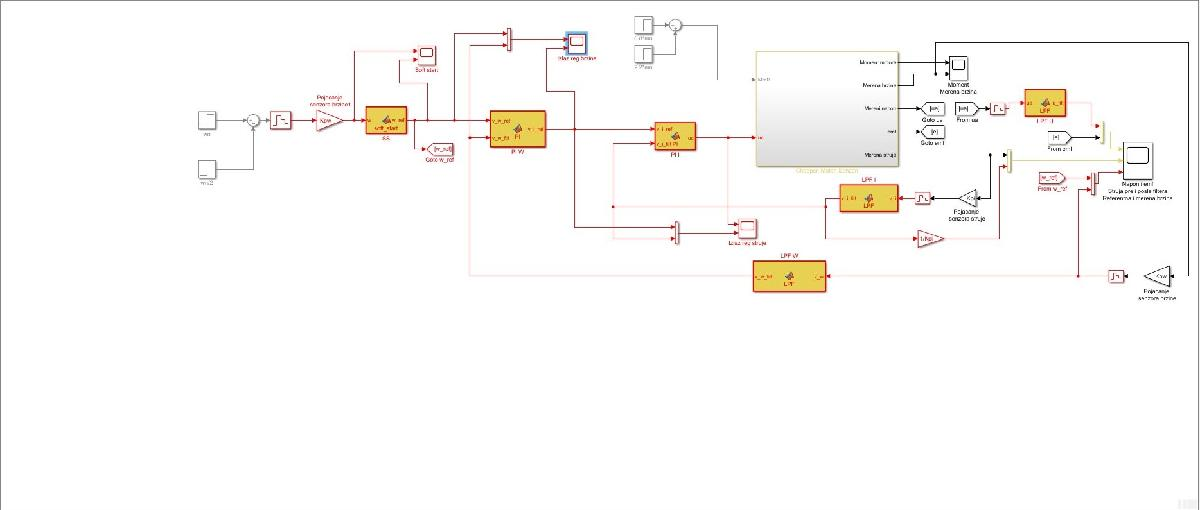

- Soft start

s = tf('s');
F_cont = 1/s;
F_disc = c2d(F_cont,Ts,'zoh');

Ova funkcija prenosa je racunata od izlaza uz rele-a do izlaza soft-start-a a rele pre nje je realizovan if-om. Kod:

function w_ref = soft_start(w)

%% Podaci

Ts=10e-6;

nn = 1430; % rpm

wn = nn*pi/30; % rad/s

K = 1000;

Kpw = 10/150;% V*s/rad

alpha_ref = wn/2*Kpw;

%% Soft-start

persistent w_ref_prev alpha_prev

  if isempty(w_ref_prev)

      w_ref_prev= 0;

  end

  if isempty(alpha_prev)

      alpha_prev=0;

  end

  % F(z) = K*Ts/z-1

  w_error=w-w_ref_prev;

  alpha=K*w_error;

  if(alpha>alpha_ref)

      alpha=alpha_ref;

  elseif(alpha<-alpha_ref)

          alpha=-alpha_ref;

  end

  w_ref=w_ref_prev+Ts*alpha_prev;

   alpha_prev=alpha;

   w_ref_prev=w_ref;

return

- PI regulator struje

Diskretizacija:

F_cont = Ki*(1+s*Ti)/s/Ti;
F_disc = c2d(F_cont,Ts,'zoh')


F_disc =
 
  0.06944 z - 0.06942
  -------------------
         z - 1
 
Sample time: 1e-05 seconds
Discrete-time transfer function.



Kod:

function uc = PI(v_i_ref,v_i_filt)

%% Podaci

uc_min=-1;

uc_max=1;

%% PI

%Ki(1+Ts/Ti/(z-1))

persistent i_error_prev uc_prev

if isempty(i_error_prev)

    i_error_prev=0;

end

if isempty(uc_prev)

    uc_prev=0;

end

i_error=v_i_ref-v_i_filt;

uc = uc_prev+0.6944*i_error-0.6942*i_error_prev;

if uc>uc_max

    uc=uc_max;

elseif uc<(uc_min)

    uc=uc_min;

end

uc_prev=uc;

i_error_prev=i_error;

return

- PI regulator brzine

Diskretizacija:

F_cont = Kw*(1+s*Tw)/s/Tw;
F_disc = c2d(F_cont,Ts,'zoh')


F_disc =
 
  44.56 z - 44.55
  ---------------
       z - 1
 
Sample time: 1e-05 seconds
Discrete-time transfer function.



Kod:

function v_i_ref = PI(v_w_ref,v_w_filt)

%% Podaci

Kpi = 0.2;% V/A

In = 26; %A

Imax=1.5*In;% A

%% PI

%Ki(1+Ts/Ti(z^-1/(1-z^-1))

persistent v_error_prev v_i_ref_prev

if isempty(v_error_prev)

    v_error_prev=0;

end

if isempty(v_i_ref_prev)

    v_i_ref_prev=0;

end

v_error=v_w_ref-v_w_filt;

v_i_ref = v_i_ref_prev+44.56*v_error-44.55*v_error_prev;

if v_i_ref>Kpi*Imax

    v_i_ref=Kpi*Imax;

elseif v_i_ref<-Kpi*Imax

    v_i_ref=-Kpi*Imax;

end

v_i_ref_prev=v_i_ref;

v_error_prev=v_error;

return

- LPF filtri

Napon:

F_cont = 1/(1+s*Tpu);
F_disc = c2d(F_cont,Ts,'zoh')


F_disc =
 
   0.003839
  ----------
  z - 0.9962
 
Sample time: 1e-05 seconds
Discrete-time transfer function.



  Kod:

function u_filt = LPF(ua)

%% Podaci

Ts=10e-6;

Tpu = 2.6e-3;

%% LPF

persistent u_filt_prev ua_prev 

% postavljanje pocetnih vrednosti

if isempty(ua_prev)

 ua_prev = 0;

end

if isempty(u_filt_prev)

 u_filt_prev= 0;

end

% F(z) = (1-e^(-Ts/T))/(z-e^(-Ts/T)))

u_filt = exp(-Ts/Tpu)*u_filt_prev + (1-exp(-Ts/Tpu))*ua_prev;

u_filt_prev = u_filt;

ua_prev = ua;

return

Struja:

F_cont = 1/(1+s*Tpi);
F_disc = c2d(F_cont,Ts,'zoh')


F_disc =
 
   0.003839
  ----------
  z - 0.9962
 
Sample time: 1e-05 seconds
Discrete-time transfer function.



Kod:

function v_i_filt = LPF(v_i)

%% Podaci

Ts=10e-6;

Tpi = 2.6e-3;

%% LPF

persistent v_i_filt_prev v_i_prev 

% postavljanje pocetnih vrednosti

if isempty(v_i_prev)

 v_i_prev = 0;

end

if isempty(v_i_filt_prev)

 v_i_filt_prev= 0;

end

% F(z) = (1-e^(-Ts/T))/(z-e^(-Ts/T)))

v_i_filt = exp(-Ts/Tpi)*v_i_filt_prev + (1-exp(-Ts/Tpi))*v_i_prev;

v_i_filt_prev = v_i_filt;

v_i_prev = v_i;

return

Brzina:

F_cont = 1/(1+s*Tpw);
F_disc = c2d(F_cont,Ts,'zoh')


F_disc =
 
  0.001998
  ---------
  z - 0.998
 
Sample time: 1e-05 seconds
Discrete-time transfer function.



Kod:

function v_w_filt = LPF(v_w)

%% Podaci

Ts=10e-6;

Tpw = 5e-3;

%% LPF

persistent v_w_filt_prev v_w_prev 

% postavljanje pocetnih vrednosti

if isempty(v_w_prev)

 v_w_prev = 0;

end

if isempty(v_w_filt_prev)

 v_w_filt_prev= 0;

end

% F(z) = (1-e^(-Ts/T))/(z-e^(-Ts/T)))

v_w_filt = exp(-Ts/Tpw)*v_w_filt_prev + (1-exp(-Ts/Tpw))*v_w_prev;

v_w_filt_prev = v_w_filt;

v_w_prev = v_w;

return

## 4) Grafici

- Izlaz soft-start-a                                                                                                                    Na gornjoj slici je ulaz u soft start a na donjoj izlaz. Sa grafika mozemo videti da iako je na ulazu soft starta brzina naglo promenjena sa nulte na nominalnu a zatim naglo spustena na polovinu nominalne soft start omogucava da se ove promene dese postepeno i to tako da se za 2s dostigne nominalna brzina( jer se mehanicke velicine sporo menjaju pa u realnosti nije moguce naglo promeniti brzinu)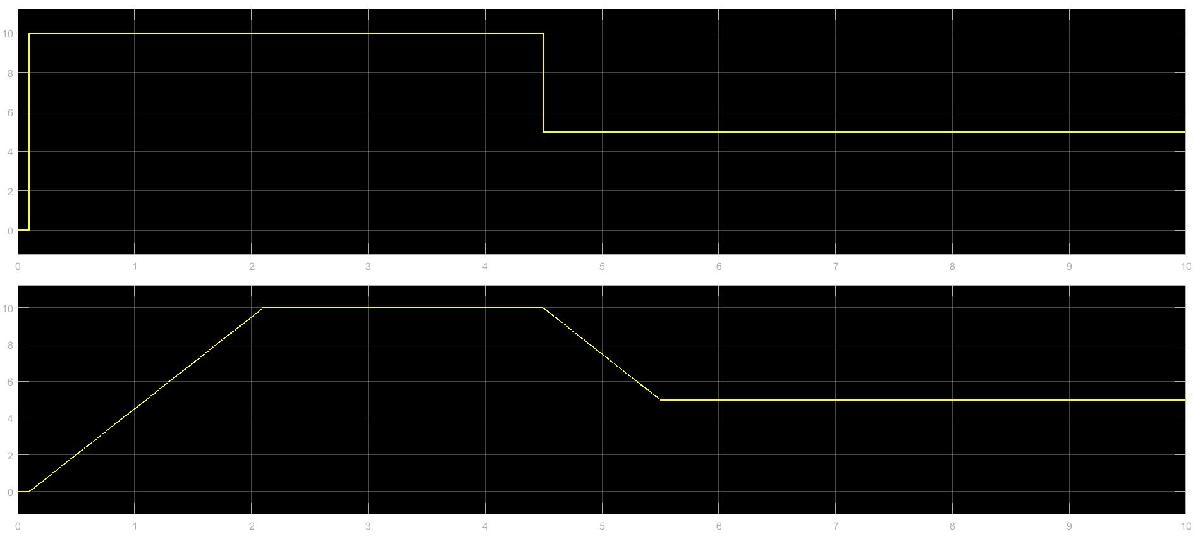

-  PI regulator struje                                                                                                       Na gornjem grafiku je prikazan izlaz regulatora struje koji je ogranicen na 1V. Na dodnjem grafiku su prikazane struja koja je izlaz iz regulatora brzine i struja iz povratne sprege. Kada dodje do preopterecenja raskida se povratna sprega i struja na izlazu ne prati struju koju daje regulator brzine zato dolazi do velikog odstupanja. Naponski signal priblizno prati yadatu brzinu i ispostovano je ogranicenje od -1V i 1V.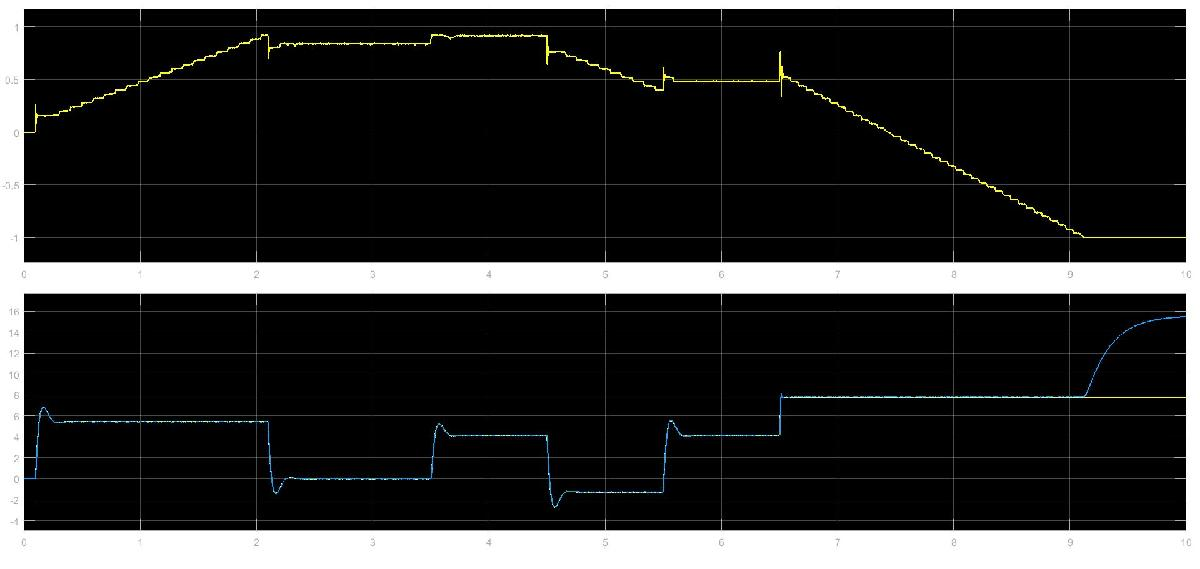

- PI regulator brzine                                                                                                      Na gornjem grafiku prikazani su ulazi a na donjem izlaz koji je napon srazmeran struji koja ulazi u regulator struje. Kada brzina krene da raste konstantnom brzinom struja naglo skace i onda ostaje konstantna sve dok se ne dostigne stacionarno stanje.($Me=J\frac{dw}{dt}+Mm->I = (5.4+0)A$). Kada brzina postane konstantna i jednaka nominalnoj opterecenje postaje nula ( jer nije modelovano trenje u sistemu) i onda struja naglo pada na nulu i tu ostaje dok ne dodje do dodavanja Mm=0.8Mn, tada struja postaje $I=\frac{Me}{PsiFn}=0.8In=4.16$. Struja ostaje na toj vrednosti dok ne dodje do konstantnog opadanja brzine kada naglo pada $Me=J\frac{dw}{dt}+Mm-> I=(-5.4+4.16)A=-1.24A$. Kada brzina postane konstantna struja se vraca na prethodno stacionarno stanje $I=0.8In=4.16A$sve dok ne dodje do preopterecenja kada ce se zakucati unajvecu mogucu vrednost $I=1.5In=7.8A$. Brzina pri opterecenju krece da opada i kada dostigne nulu pri prevelikom opterecenju motor krece da se obrce u suprotnom smeru.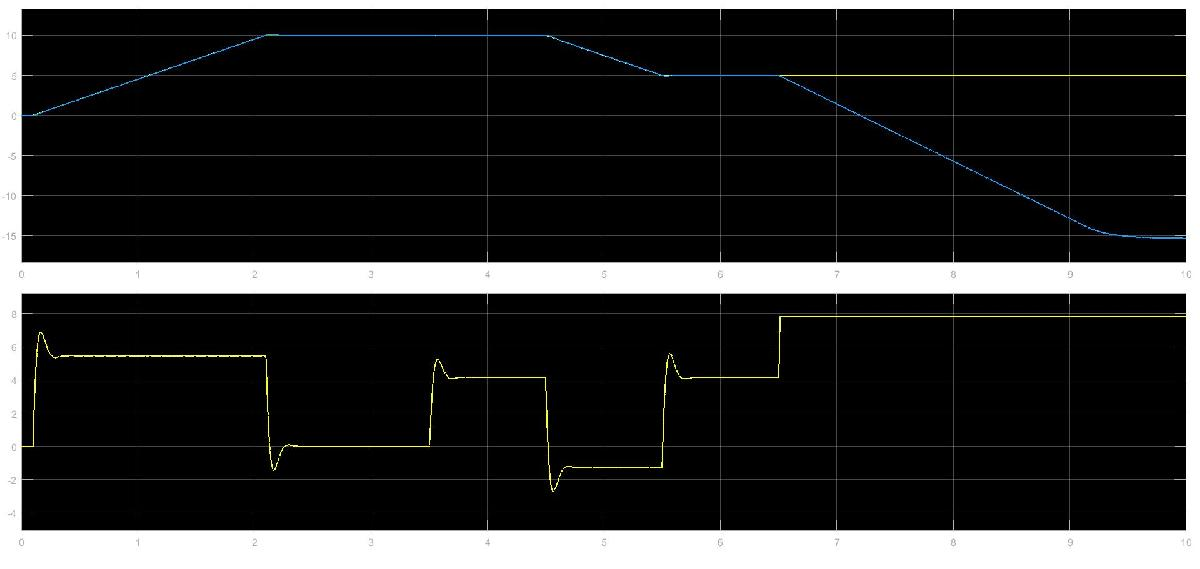

- Napon i emf, struja pre i posle filtriranja, referentna i merena brzina                   Vidimo da sto je struja veca to je veca razlika izmedju emf i Ua  jer ih povezuje    formula $Ua = RaIa+e$ u stacionarnom stanju. Kada je struja nula oni ce se potpuno poklapati, kada je pozitivna Ua ce biti vece a kada je negativna Ua ce biti manje.